# Multilayer Insulation Modeling

%clc; clear; clear all

## Initial Temperature

T0 = 10; % C

## Ambient Heat Flux

Q_rad = @(~, state) Sol_rad(state.time);
%Q_total = 1602.2; %J/s

## Material Properties

%['Thermal Conductivity',  'Mass Density', 'Specific Heat',    'emissivity']
        %[W/(m K),           kg/(m^3),       J/(kg K),                     ]
mat_1 = [318,                  19300,          125.604,         0.025];  % Gold
mat_2 = [ NaN,                   1520,             NaN,          0.86];  % 'virgin' carbon fiber composite pyrolysis model.
mat_3 = [237,                   2700,          921.096,          0.04];  % Aluminum Foil (only difference is emissivity)
mat_4 = [ NaN,                    549,             NaN,          0.86];  % 'resin' carbon fiber composite pyrolysis model.
mat_5 = [237,                   2700,          921.096,          0.09];  % Aluminum (Polished)

## Temperature Dependent Carbon Fiber Properties

%CF Material 1
k1 =  @(~,state) 0.59 - 0.00065 * state.u;
Cp1 = @(~,state) 160 + 2.4 * state.u;

%CF Material 2
k2 =  @(~,state) 5.5e-10 * (state.u).^3;
Cp2 = @(~,state) 1054 + 0.7 * state.u;

## Material Layering

Au1_layer = 96;
CF1_layer = 2;
Al1_layer = 1;
CF2_layer = 1;
Al2_layer = 1;
%Au2_layer = 2; 

## Geometry

% All Materials 
Height = 1; 

% Material 1
Width1 = Au1_layer * 0.00001406; % (m) # layers at 0.0140625 mm each

% Material 2
Width2 = CF1_layer * 0.000127; % (m) # layers at 0.127 mm each

% Material 3
Width3 = Al1_layer * 0.00013; % (m) # layers at 0.130 mm each (Guage 36)
%Au2_layer * 0.000812;% (m) # layers at 0.812 mm each (Guage 20)

% Material 4
Width4 = CF2_layer * 0.00038; % (m) # layers at 0.380 mm each

% Material 5 
Width5 = Al1_layer * 0.001; % (m) # layers at 1.0 mm each

## Geometry Calcs

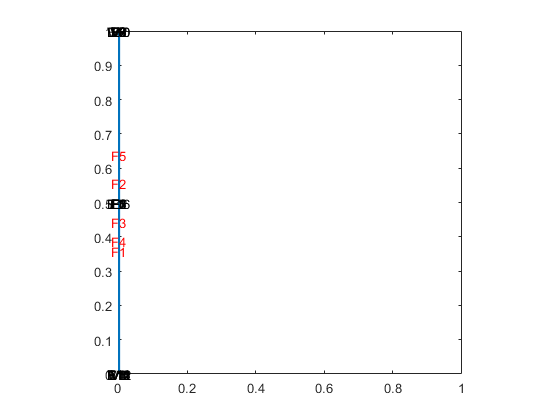

Wall_thermal_mod = createpde('thermal', 'transient');
%{
mat 1 = 0.1m thick
mat 2 = 0.05m thick
mat 3 = 0.1m thick
mat 4 = 0.5m thick
mat 5 = 0.1m thick
%}
Widh2a = Width1 + Width2;
Widh3a = Widh2a + Width3; 
Widh4a = Widh3a + Width4;
Widh5a = Widh4a + Width5;

Geo1 = [...
    3.0000    3.0000    3.0000    3.0000    3.0000
    4.0000    4.0000    4.0000    4.0000    4.0000
    0.0000    Width1    Widh2a    Widh3a    Widh4a
    Width1    Widh2a    Widh3a    Widh4a    Widh5a
    Width1    Widh2a    Widh3a    Widh4a    Widh5a
    0.0000    Width1    Widh2a    Widh3a    Widh4a
    Height    Height    Height    Height    Height
    Height    Height    Height    Height    Height
         0         0         0         0         0
         0         0         0         0         0];

sf =    'R1+R2+R3+R4+R5';
ns = [...
    82    82    82    82    82
    49    50    51    52    53];

panel_dim = decsg(Geo1, sf, ns);
geometryFromEdges(Wall_thermal_mod, panel_dim);
pdegplot(panel_dim, 'EdgeLabels','on',"FaceLabels",'on', 'CellLabels', 'on', 'VertexLabels', 'on')
xlim([0 1])
ylim([0 1])

### Material Faces

% Change Material Faces after runing geometry section once
MF1 = 1; 
MF2 = 3;
MF3 = 4;
MF4 = 5;
MF5 = 2;

### Material Edges

% Change Material Edges after runing geometry section once
ME1 = [1,  3];
ME2 = [3,  4];
ME3 = [4,  5];
ME4 = [5, 16];
ME5 = [16, 2];

## Material Property Assignment

thermalProperties(Wall_thermal_mod,...
    "ThermalConductivity",mat_1(1),...
    "MassDensity", mat_1(2),...
    "SpecificHeat",mat_1(3),...
    "Face", MF1 );

thermalProperties(Wall_thermal_mod,...
    "ThermalConductivity", k1,...
    "MassDensity", mat_2(2),...
    "SpecificHeat", Cp1,...
    "Face", MF2);

thermalProperties(Wall_thermal_mod,...
    "ThermalConductivity", mat_3(1),...
    "MassDensity", mat_3(2),...
    "SpecificHeat",mat_3(3),...
    "Face", MF3);

thermalProperties(Wall_thermal_mod,...
    "ThermalConductivity", k2,...
    "MassDensity", mat_4(2),...
    "SpecificHeat", Cp2,...
    "Face", MF4);

thermalProperties(Wall_thermal_mod,...
    "ThermalConductivity",mat_5(1),...
    "MassDensity", mat_5(2),...
    "SpecificHeat",mat_5(3),...
    "Face", MF5);


## Boundry Conditions

%Edge1
Wall_thermal_mod.StefanBoltzmannConstant = 5.670373E-8;
thermalBC(Wall_thermal_mod, 'AmbientTemperature', T0,'Edge', ME1, "Emissivity", mat_1(4), "Vectorized", 'on');
thermalBC(Wall_thermal_mod, 'AmbientTemperature', T0,'Edge', ME2, "Emissivity", mat_2(4), "Vectorized", 'on');
thermalBC(Wall_thermal_mod, 'AmbientTemperature', T0,'Edge', ME3, "Emissivity", mat_3(4), "Vectorized", 'on');
thermalBC(Wall_thermal_mod, 'AmbientTemperature', T0,'Edge', ME4, "Emissivity", mat_4(4), "Vectorized", 'on');
thermalBC(Wall_thermal_mod, 'AmbientTemperature', T0,'Edge', ME5, "Emissivity", mat_5(4), "Vectorized", 'on');
thermalBC(Wall_thermal_mod, 'Edge', ME1, "HeatFlux", Q_rad, "Vectorized", 'on');

## Initial Conditions

%insert
thermalIC(Wall_thermal_mod, T0, "Face", [1,2,3,4,5]);

## Generate Mesh

mesh = generateMesh(Wall_thermal_mod);

## Solve

t_max = 36000;
n_val = 1000;
tlist = linspace(0, t_max, n_val);
Wall_thermal_mod;

thermalresults = solve(Wall_thermal_mod,tlist);

temp = thermalresults.Temperature;
[qTx,qTy] = evaluateHeatFlux(thermalresults);

## Plotting Heat Flux Vectors

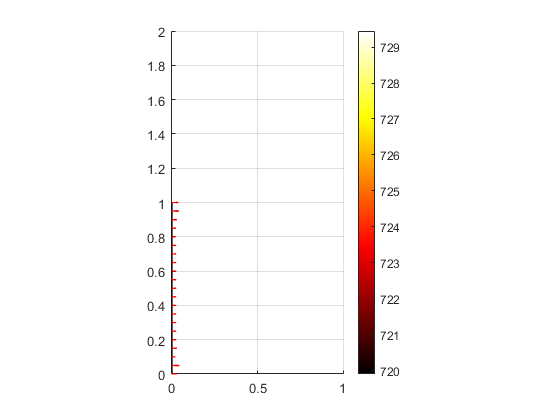

figure
pdeplot(Wall_thermal_mod,'XYData',temp(:,end),'Contour','on', ...
                     'FlowData',[qTx(:,end) qTy(:,end)], ...
                     'ColorMap','hot')
 axis([0 1 0 2])
 grid on

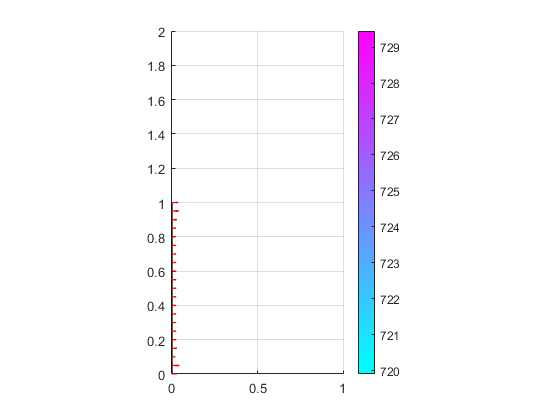

figure
pdeplot(Wall_thermal_mod,'XYData',temp(:,end),'Contour','on', ...
                     'FlowData',[qTx(:,end) qTy(:,end)], ...
                     'ColorMap','cool')
 axis([0 1 0 2])
 grid on

## Locating Closest Node on Edge

getClosestNode = @(p,x,y) min((p(1,:) - x).^2 + (p(2,:) - y).^2);                 
[~, nid1] = getClosestNode( mesh.Nodes, 0.20, 2.5 ); % Heat Receiving Edge of Material 1
[~, nid2] = getClosestNode( mesh.Nodes, 0.30, 2.5 ); % Boundry Between Material 1 and Material 2
[~, nid3] = getClosestNode( mesh.Nodes, 0.35, 2.5 ); % Boundry Between Material 2 and Material 3
[~, nid4] = getClosestNode( mesh.Nodes, 0.45, 2.5 ); % Boundry Between Material 3 and Material 4
[~, nid5] = getClosestNode( mesh.Nodes, 0.50, 2.5 ); % Boundry Between Material 4 and Material 5
[~, nid6] = getClosestNode( mesh.Nodes, 0.50, 2.5 ); % Non-Contact Edge of Material 5

## Edge Transient Temperature 

T_mat1 = temp(nid1, :);
T_mat_1_2 = temp(nid2, :);
T_mat_2_3 = temp(nid3, :);
T_mat_3_4 = temp(nid4, :);
T_mat_4_5 = temp(nid5, :);
T_mat5 = temp(nid6, :);

t = tlist(1:size(temp,2)) ;

## Edge Temperature Plots

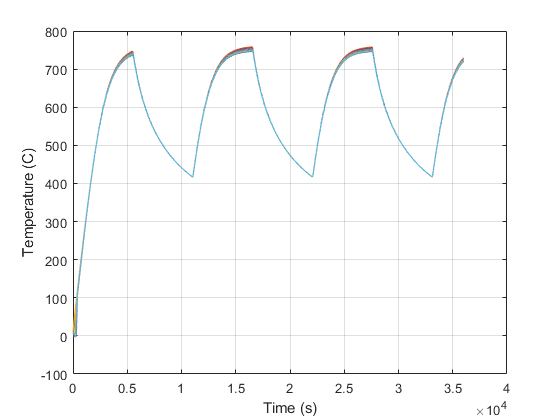

plot(tlist, temp)
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')

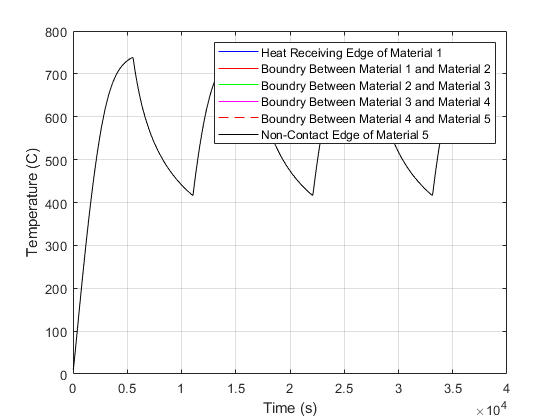

plot(t, T_mat1,   'b',...
    t, T_mat_1_2, 'r',...
    t, T_mat_2_3, 'g',...
    t, T_mat_3_4, 'm',...
    t, T_mat_4_5, 'r--',...
    t, T_mat5,    'k')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')
legend('Heat Receiving Edge of Material 1','Boundry Between Material 1 and Material 2',...
    'Boundry Between Material 2 and Material 3', 'Boundry Between Material 3 and Material 4',...
    'Boundry Between Material 4 and Material 5', 'Non-Contact Edge of Material 5')

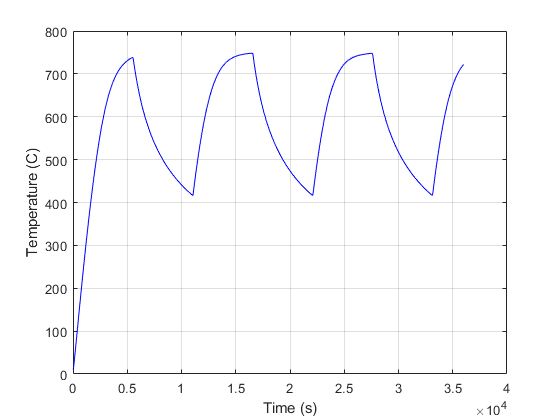

% Heat Receiving Edge of Material 1
plot(t, T_mat1, 'b')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val1 = max(T_mat1);
find_min1 = islocalmin(T_mat1);
min_val1 = 0;

for i = 1:1:1000
    if find_min1(i) == 1
        min_val1 = T_mat1(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val1)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val1)

Min Temperature on Mat 1 = 416.40 C

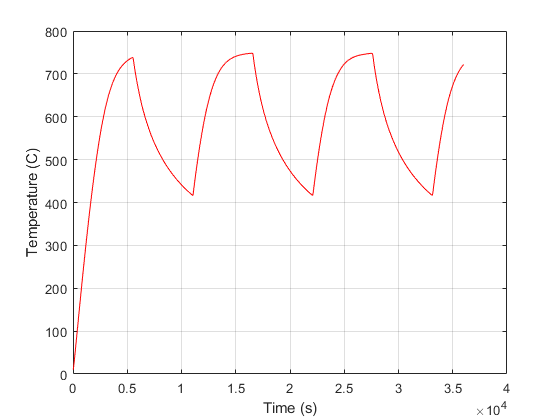

% Boundry Between Material 1 and Material 2
plot(t, T_mat_1_2, 'r')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val2 = max(T_mat_1_2);
find_min2 = islocalmin(T_mat_1_2);
min_val2 = 0;

for i = 1:1:1000
    if find_min2(i) == 1
        min_val2 = T_mat_1_2(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val2)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val2)

Min Temperature on Mat 1 = 416.40 C

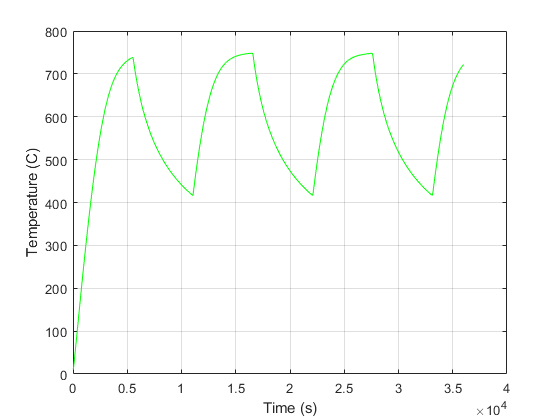

% Boundry Between Material 2 and Material 3
plot(t, T_mat_2_3, 'g')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val3 = max(T_mat_2_3);
find_min3 = islocalmin(T_mat_2_3);
min_val3 = 0;

for i = 1:1:1000
    if find_min3(i) == 1
        min_val3 = T_mat_2_3(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val3)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val3)

Min Temperature on Mat 1 = 416.40 C

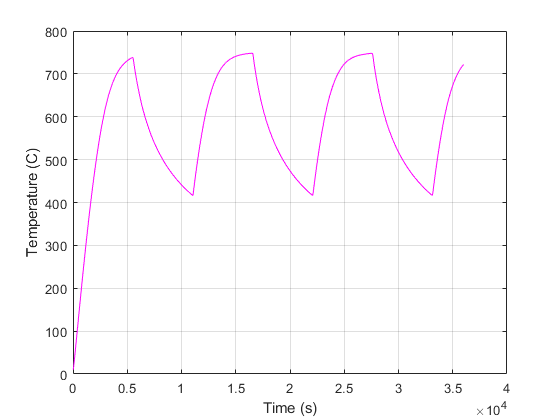

% Boundry Between Material 3 and Material 4
plot(t, T_mat_3_4, 'm')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val4 = max(T_mat_3_4);
find_min4 = islocalmin(T_mat_3_4);
min_val4 = 0;

for i = 1:1:1000
    if find_min4(i) == 1
        min_val4 = T_mat_3_4(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val4)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val4)

Min Temperature on Mat 1 = 416.40 C

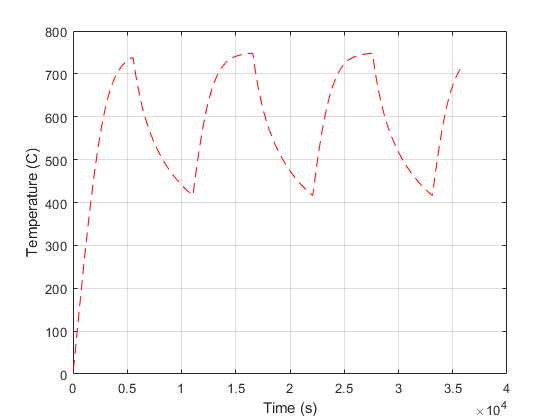

% Boundry Between Material 4 and Material 5
plot(t, T_mat_4_5, 'r--')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val5 = max(T_mat_4_5);
find_min5 = islocalmin(T_mat_4_5);
min_val5 = 0;

for i = 1:1:1000
    if find_min5(i) == 1
        min_val5 = T_mat_4_5(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val5)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val5)

Min Temperature on Mat 1 = 416.40 C

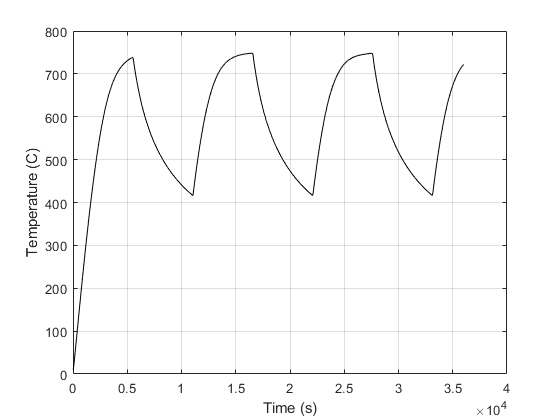

% Non-Contact Edge of Material 5
plot(t, T_mat5, 'k')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')


max_val6 = max(T_mat5);
find_min6 = islocalmin(T_mat5);
min_val6 = 0;

for i = 1:1:1000
    if find_min6(i) == 1
        min_val6 = T_mat5(i);
        break
    end
end

fprintf('Max Temperature on Mat 1 = %.2f C', max_val6)

Max Temperature on Mat 1 = 748.35 C

fprintf('Min Temperature on Mat 1 = %.2f C', min_val6)

Min Temperature on Mat 1 = 416.40 C

## Heat Rate Evaluation

Qn1 = evaluateHeatRate(thermalresults,'Edge', ME1);
Qn2 = evaluateHeatRate(thermalresults,'Edge', ME2);
Qn3 = evaluateHeatRate(thermalresults,'Edge', ME3);
Qn4 = evaluateHeatRate(thermalresults,'Edge', ME4);
Qn5 = evaluateHeatRate(thermalresults,'Edge', ME5);

## Heat Rate Plotting

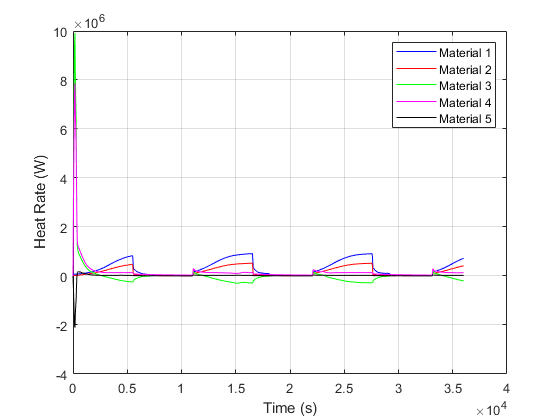

plot(t, Qn1, 'b',...
     t, Qn2, 'r',...
     t, Qn3, 'g',...
     t, Qn4, 'm',...
     t, Qn5, 'k')
grid on
xlabel('Time (s)')
ylabel('Heat Rate (W)')
legend('Material 1','Material 2', 'Material 3', 'Material 4', 'Material 5')

## Save Results

Material =  {'Q Edge',...
                'Mat 1 Layers',...
                'Mat 2 Layers',...
                'Mat 3 Layers',...
                'Mat 4 Layers',...
                'Mat 5 Layers',...
                'Edge 1 Max T (C)',...
                'Mat 1 Max T (C)',...
                'Mat 2 Max T (C)',...
                'Mat 3 Max T (C)',...
                'Mat 4 Max T (C)',...
                'Mat 5 Max T (C)',... 
                'Edge 1 Min T (C)',...
                'Mat 1 Min T (C)',...
                'Mat 2 Min T (C)',...
                'Mat 3 Min T (C)',...
                'Mat 4 Min T (C)',...
                'Mat 5 Min T (C)'}

Material = 1×18 cell array
    {'Q Edge'}    {'Mat 1 Layers'}    {'Mat 2 Layers'}    {'Mat 3 Layers'}    {'Mat 4 Layers'}    {'Mat 5 Layers'}    {'Edge 1 Max T (C)'}    {'Mat 1 Max T (C)'}    {'Mat 2 Max T (C)'}    {'Mat 3 Max T (C)'}    {'Mat 4 Max T (C)'}    {'Mat 5 Max T (C)'}    {'Edge 1 Min T (C)'}    {'Mat 1 Min T (C)'}    {'Mat 2 Min T (C)'}    {'Mat 3 Min T (C)'}    {'Mat 4 Min T (C)'}    {'Mat 5 Min T (C)'}


Row_Disp =     [0,...
                Au1_layer,...
                CF1_layer,...
                Al1_layer,...
                CF2_layer,...
                Al2_layer,...
                max_val1,...
                max_val2,...
                max_val3,...
                max_val4,...
                max_val5,...
                max_val6,...
                min_val1,...
                min_val2,...
                min_val3,...
                min_val4,...
                min_val5,...
                min_val6]

Row_Disp =          0   96.0000    2.0000    1.0000    1.0000    1.0000  748.3534  748.3534  748.3534  748.3534  748.3534  748.3534  416.3982  416.3982  416.3982  416.3982  416.3982  416.3982


%Tab = table(Material)
Tab = table(Row_Disp)

Tab = table
      Row_Disp   
    _____________

    [1×18 double]


%writetable(Tab ,'Thermal_funcs.xlsx')
writetable(Tab,'Thermal_funcs.xlsx',"WriteMode","append");